% s_nmfAnalysis.m

## Purpose

Spectrophotometric measurements of radiance collected from 4 subjects when their tongue (or lower lip area) was illuminated with a 415 nm light at different intensities.  We combine all the data into one matrix and use non-negative matrix factorization to estimate non-negative principal components.  The 415 nm light had a 450 nm shortpass filter to block energy in the longer wavelengths from reaching the tissue, and a 475 nm longpass filter on the spectrophotometer to any residual reflected light from reaching the spectrophotometer. 

### Notes 

#### SNR

To verify that we were measuring tissue fluorescence, and not reflectance, we made the following measurements and calculations

- We measured the amount of the 415 nm light that passed through the 450 nm light and illuminated a white surface, using a spectrophotometer with a 475 nm longpass filter. 

- To estimate the amount of the 415 nm light that would be reflected from the tongue and measured by the spectrophotometer, we multiplied the measured reflected light with the mean tongue reflectance (measured across 12 different subjects).

#### Intensity

The data measured for each subject was for one light, and at different intensities. Hence, the data within subjects differ only by a scale factor related to intensity. We can have a separate script to analyze how both fluorescence and expected tissue reflectance increases with the intensity of excitation light. 

We do not have the measurement of reflected light for the 170 mA case, although we did measure intensity of fluorescence for this light.

see s_LipAFI4difLights.m data  for data from one subject whose tongue (and lower lip area) was illuminated by three different lights ( with peak energy at 405, 415 and 450 nm) at three different intensities) 

#### Basis

Within each subject, there would be only one basis function, and if all subject data was the same, then they would be just one basis function. The individual differences make it possible to separate the effects of porphyrins and, in the case of at least one subject, chlorophyll on the tongue. 

## Executive Summary

Keeping in mind that NNMF has inherent challenges, including sensitivity to initialization, potential overfitting, and **non-unique solutions, **there are still some insights that can be gained.

- Just plotting the tongue measurement data, we can see that we have at least two (and in case of measurements made after lunch, three) spectral basis functions. One is for bulk, one for porphyrins and one for chlorophyll (when we add in measurements made after lunch)

- Although nnmf does not always produce the same result, usually when plot the second and third basis, they look like the spectral emissions of porphyrins and chlorophyll 

- Just plotting the lip measurement data, we can see that they look the same and might therefore expect only one basis is required.  However, two spectral basis functions seem to be necessary. Note however, that we did not take into account the effect of absorption of collagen fluorescence by blood, and FAD.  

Collagen and FAD are the two fluorophores most often mentioned in the literature to explain tissue fluorescence in the oral cavity. keratin is ignored, although you would expect to see keratin fluorescence on the tongue and not on the lip

**Question for another analysis: Combine data from all three lights (404, 415, 450)**

Can we explain the lip fluorescence with two basis

- collagen * blood transmission

- FAD

Can we explain the tongue fluorescence with three or four basis

- collagen * blood transmission

- FAD

- porphyrins (tongue)

- chlorophyll (tongue)

- possibly keratin  (tongue)

## set paths

cd /Users/joyce/Github/isetcam; addpath(genpath(pwd));
cd /Users/joyce/Github/isetfluorescence; addpath(genpath(pwd));
cd /Users/joyce/Github/oraleye/; addpath(genpath(pwd));
cd /users/joyce/Github/oe_tongue_lip/; addpath(genpath(pwd));

ieInit;

## Data

The data files were transferred from our archive to oe_tongue_lip/local/data

data for brian and zhenyi in Lab Measurements/2024-03-07 (415nm Tongue+lip measurements

data for joyce and doug in Lab Measurements/2024-03-08 (415nm Tongue+lip measurements

datadir = fullfile(oreyeRootPath,'local','data','20240307'); 

allData = [];
wave = 500:5:705; % only analyze spectral measurements in this range

zhenyiTongueFiles = dir(fullfile(datadir,'zhenyi/*Tongue*'));
thisData = zeros(numel(wave),numel(zhenyiTongueFiles));
for ii=1:numel(zhenyiTongueFiles)
    thisData(:,ii) = ieReadSpectra(fullfile(datadir,'zhenyi',zhenyiTongueFiles(ii).name),wave);
end
zhenyiTongue = thisData;
allData = [allData,thisData];

brianTongue = dir(fullfile(datadir,'brian/*tongue*'));
thisData = zeros(numel(wave),numel(brianTongue));
for ii=1:numel(brianTongue)
    thisData(:,ii) = ieReadSpectra(fullfile(datadir,'brian',brianTongue(ii).name),wave);
end
brianTongue = thisData;
allData = [allData,thisData];

joyceTongue = dir(fullfile(datadir,'joyce1/*tongue*'));
thisData = zeros(numel(wave),numel(joyceTongue));
for ii=1:numel(joyceTongue)
    thisData(:,ii) = ieReadSpectra(fullfile(datadir,'joyce1',joyceTongue(ii).name),wave);
end
joyceTongue = thisData;
allData = [allData,thisData];

dougTongue = dir(fullfile(datadir,'doug/*tongue*'));
thisData = zeros(numel(wave),numel(dougTongue));
for ii=1:numel(dougTongue)
    thisData(:,ii) = ieReadSpectra(fullfile(datadir,'doug',dougTongue(ii).name),wave);
end
dougTongue = thisData;
allData = [allData,thisData];

### Plot the data

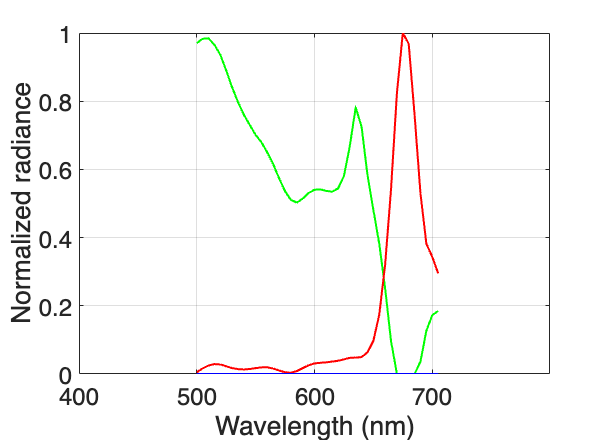

ieNewGraphWin;
plot(wave,allData,'k','LineWidth',2); hold on;
title('Tongue Fluorescence (N =4)');
fontsize(gca,16,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');	
xlim([400 800]);

Calculate a non-negative spectral basis

NNMF has inherent challenges, including sensitivity to initialization, potential overfitting, and **non-unique solutions**

**Perhaps we can initialize using fluorophore basis (Basis) and non-negative coefficients (H)**

- Rows of H represent the coefficients of linear combinations of original variables

- Indicates how much each factor (column of W) contributes to reconstructing each column of X

- The product of W and H approximates the original data matrix X ≈ WH, where

-     k is the number of components chosen for factorization

-     k is typically smaller than the rank of X, providing a compressed approximation

- In matlab "W and H are normalized so that the rows of H have unit length. The columns of W are ordered by decreasing length."

k is 1

 percent var acc for 86.78%


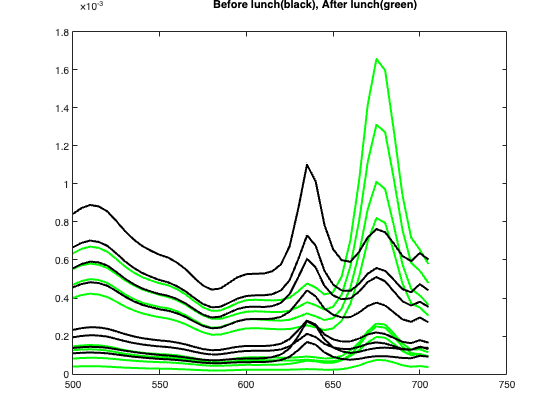

k is 2

 percent var acc for 142.26%


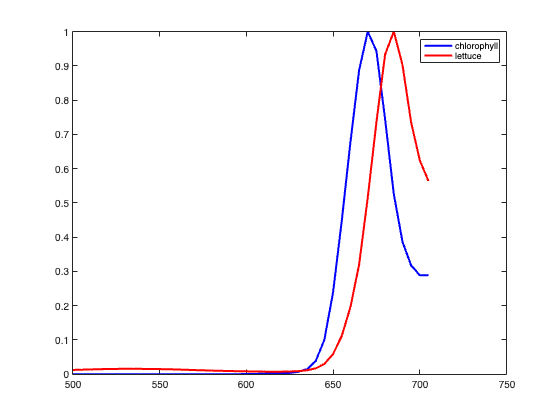

k is 3

 percent var acc for 102.39%


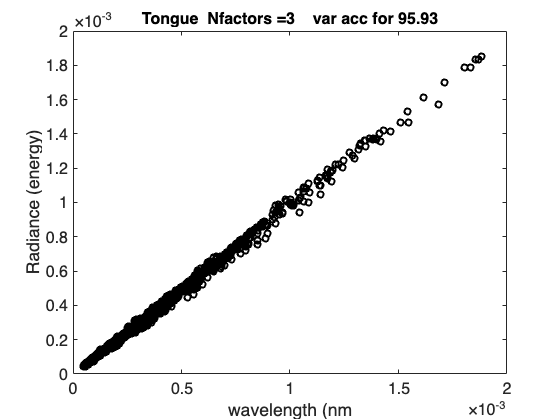


% H is a kxn matrix where n is the original number of columns in allData, and 
% k is the number of factors;
[~,cols] = size(allData);
for k = 1:4
    [Basis,H] = nnmf(allData,k);
    total_variance = sum(var(allData));
    approximation = Basis * H;
    explained_variance = sum(var(approximation));
    percent_variance = (explained_variance / total_variance) * 100;
    fprintf('k is %i',k);
    fprintf(' percent var acc for %.2f%%\n',percent_variance);
    figure;
    for jj = 1:cols
        plot(approximation(:,jj),allData(:,jj),'ko','LineWidth',2); hold on;
    end
    title(['Tongue  Nfactors =' num2str(k), '    var acc for ' num2str(percent_variance,4)]);
    fontsize(gca,16,"pixels");
    xlabel('wavelength (nm');
    ylabel('Radiance (energy)');
end

Plot the two factors that account for most of the variance

Although the solutions are not unique, they most often show that two factors are required, one for bulk tissue fluorescence and one for porphyrins.  Sometimes, we can also see the effect of chlorophyll .... 

% plot the Factors (Basis)
Basis = ieScale(Basis,1);
ieNewGraphWin;
plot(wave,Basis(:,1),'LineWidth',2,'color','g');
hold on;
plot(wave,Basis(:,2),'LineWidth',2,'color','r');
grid on;
plot(wave,Basis(:,3),'LineWidth',2,'color','b');
grid on;
plot(wave,Basis(:,4),'LineWidth',2,'color','k');
grid on;
set(gca,'ylim',[0 1]);
set(gca,'xlim',[400 800]);
set(gca,'fontsize',16);
set(gca,'xtick',400:100:700);
xlabel('Wavelength (nm)');
ylabel('Normalized radiance');

## Chlorophyll

One subject had different measurements before and after eating a salad for lunch.  We add in the measurements of her tongue fluorescence that were made after lunch. 

joyceTongue2 = dir(fullfile(datadir,'joyce2/*tongue*'));
thisData = zeros(numel(wave),numel(joyceTongue2));
for ii=1:numel(joyceTongue2)
    thisData(:,ii) = ieReadSpectra(fullfile(datadir,'joyce2',joyceTongue2(ii).name),wave);
end
joyceTongue2 = thisData;

ieNewGraphWin; plot(wave,thisData,'g','LineWidth',2); hold on;
plot(wave,joyceTongue,'k','LineWidth',2);
title('Before lunch(black), After lunch(green)');

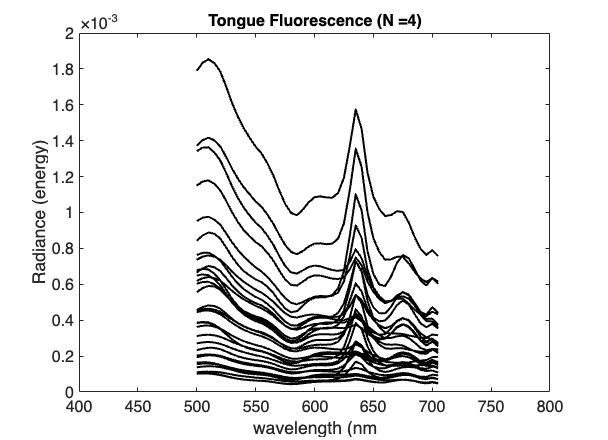


chlorophyll = ieReadSpectra('ChlorophyllA_emission.mat',wave); 
lettuce = ieReadSpectra('spd-2024-03-19-lettuce1-415nm-1A.mat',wave); 
ieNewGraphWin; plot(wave,chlorophyll/max(chlorophyll(:)),'b','LineWidth',2); hold on;
plot(wave,lettuce/max(lettuce(:)),'r','LineWidth',2); 
legend('chlorophyll','lettuce');

% add in joyceTongue2 to the larger subject data matrix
allData = [allData,thisData];

We plot the data 

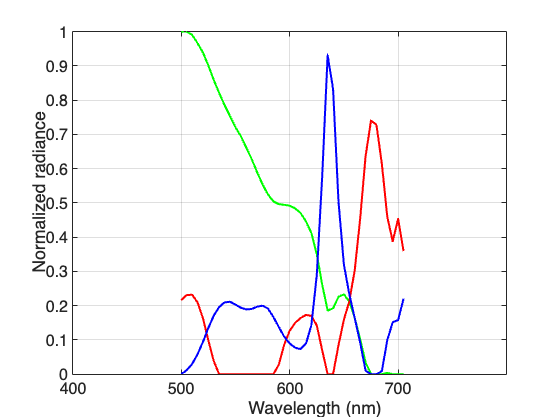

figure; plot(wave,allData,'k','LineWidth',2)
title('Tongue Fluorescence (N =5:effect of eating salad');
fontsize(gca,16,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');	
xlim([400 800]);

We redo the nnmf analysis 

k is 1

 percent var acc for 53.60%


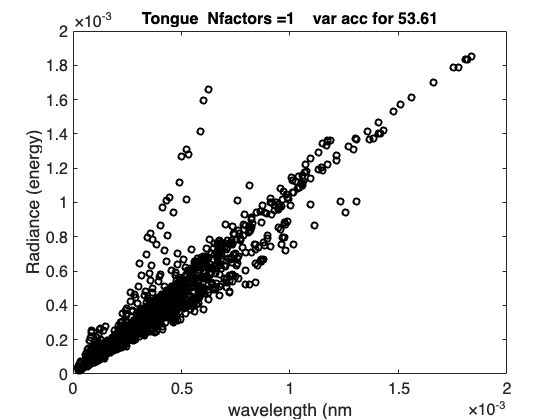

k is 2

 percent var acc for 108.83%


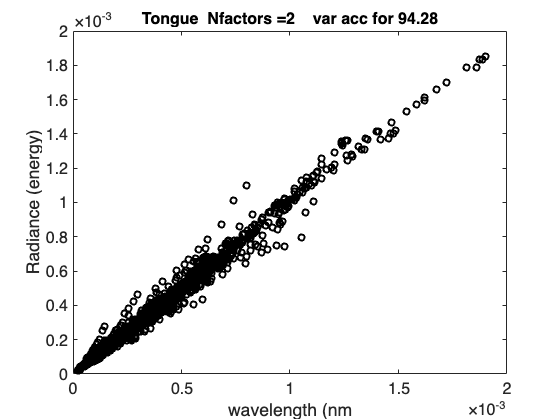

k is 3

 percent var acc for 104.35%


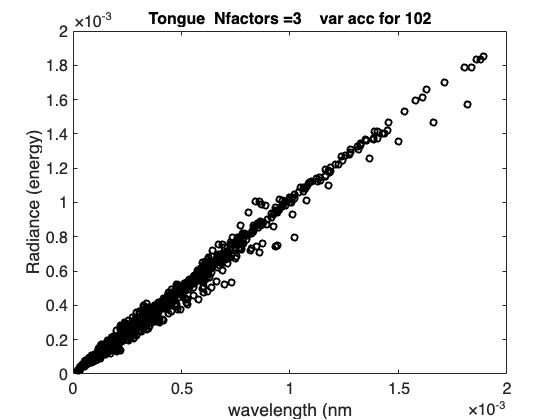

k is 4

 percent var acc for 95.30%


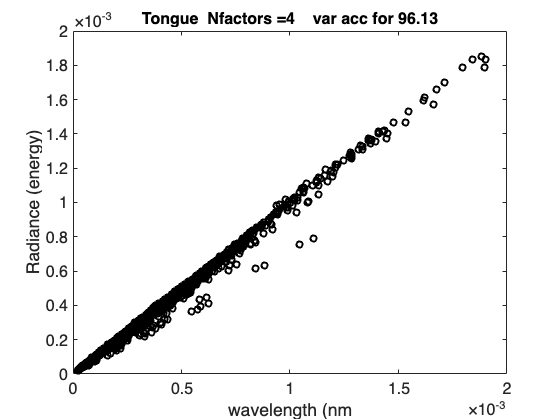

[~,cols] = size(allData);
for k = 1:4
    [Basis,H] = nnmf(allData,k);
    total_variance = sum(var(allData));
    approximation = Basis * H;
    explained_variance = sum(var(approximation));
    percent_variance = (explained_variance / total_variance) * 100;
    fprintf('k is %i',k);
    fprintf(' percent var acc for %.2f%%\n',percent_variance);
    figure;
    for jj = 1:cols
        plot(approximation(:,jj),allData(:,jj),'ko','LineWidth',2); hold on;
    end
    title(['Tongue  Nfactors =' num2str(k), '    var acc for ' num2str(percent_variance,4)]);

    fontsize(gca,16,"pixels");
    xlabel('wavelength (nm');
    ylabel('Radiance (energy)');
end

Solutions based on nnmf are not unique, so we may want to initialize the basis and weights, and then run. Still, notice that for the tongue, the data can be explained by two or three factors - a bulk tissue fluorescence, porphyrins and chlorophyll


Basis = ieScale(Basis,1);
ieNewGraphWin;
plot(wave,Basis(:,1),'g','LineWidth',2); hold on;
plot(wave,Basis(:,2),'r','LineWidth',2); hold on;
plot(wave,Basis(:,3),'b','LineWidth',2); hold on;
plot(wave,Basis(:,4),'k','LineWidth',2); hold on;
grid on;
set(gca,'ylim',[0 1]);
set(gca,'xlim',[400 800]);
set(gca,'fontsize',24);
set(gca,'xtick',400:100:700);
xlabel('Wavelength (nm)');
ylabel('Normalized radiance');



## Now for the lip

reset allData to contain only data from lip

Plot the data for all subjects to show that even after adding the data measured after lunch, we do not see porphyrins or chlorophyll fluorescence on the lower lip

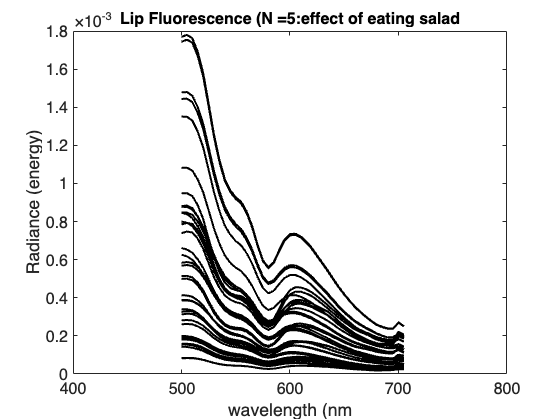

allData = [];

zhenyiLip = dir(fullfile(datadir,'zhenyi/*lip*'));
thisData = zeros(numel(wave),numel(zhenyiLip));
for ii=1:numel(zhenyiLip)
    thisData(:,ii) = ieReadSpectra(fullfile(datadir,'zhenyi',zhenyiLip(ii).name),wave);
end
zhenyiLip = thisData;
allData = [allData,thisData];

brianLip = dir(fullfile(datadir,'brian/*lip*'));
thisData = zeros(numel(wave),numel(brianLip));
for ii=1:numel(brianLip)
    thisData(:,ii) = ieReadSpectra(fullfile(datadir,'brian',brianLip(ii).name),wave);
end
brianLip = thisData;
allData = [allData,thisData];

joyceLip = dir(fullfile(datadir,'joyce1/*lip*'));
thisData = zeros(numel(wave),numel(joyceLip));
for ii=1:numel(joyceLip)
    thisData(:,ii) = ieReadSpectra(fullfile(datadir,'joyce1',joyceLip(ii).name),wave);
end
joyceLip = thisData;
allData = [allData,thisData];

dougLip = dir(fullfile(datadir,'doug/*lip*'));
thisData = zeros(numel(wave),numel(dougLip));
for ii=1:numel(dougLip)
    thisData(:,ii) = ieReadSpectra(fullfile(datadir,'doug',dougLip(ii).name),wave);
end
dougLip = thisData;

allData = [allData,thisData];joyceLip2 = dir(fullfile(datadir,'joyce2/*lip*'));
thisData = zeros(numel(wave),numel(joyceLip2));
for ii=1:numel(joyceLip2)
    thisData(:,ii) = ieReadSpectra(fullfile(datadir,'joyce2',joyceLip2(ii).name),wave);
end
joyceLip2 = thisData;

k is 1

 percent var acc for 98.93%


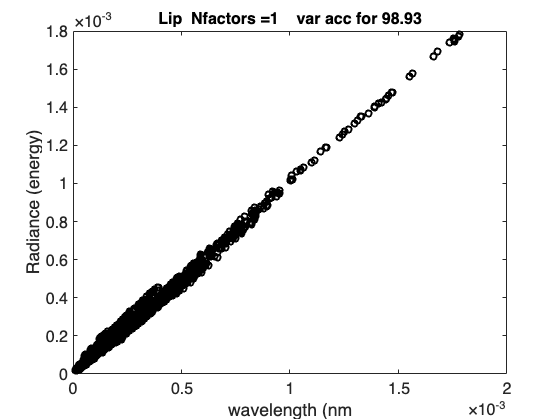

k is 2

 percent var acc for 95.83%


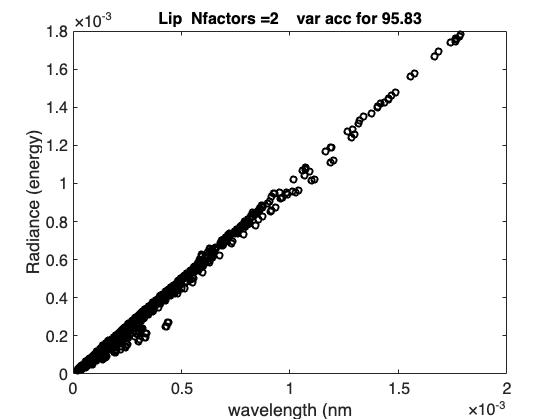

k is 3

 percent var acc for 110.04%


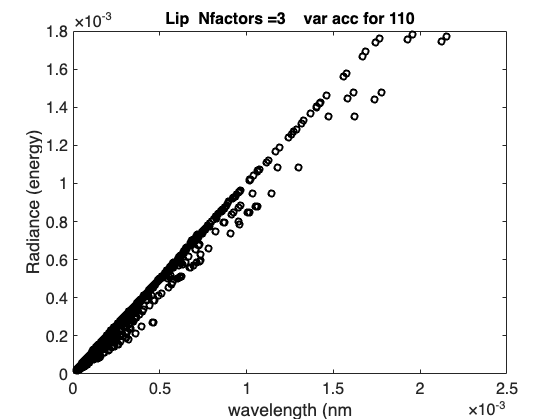

k is 4

 percent var acc for 94.61%


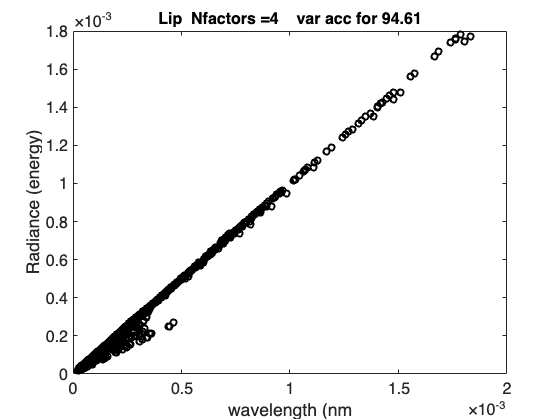

allData = [allData,thisData];

figure; plot(wave,allData,'k','LineWidth',2)
title('Lip Fluorescence (N =5:effect of eating salad');
fontsize(gca,16,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');	
xlim([400 800]);


nnmf on data from the lip only  - 

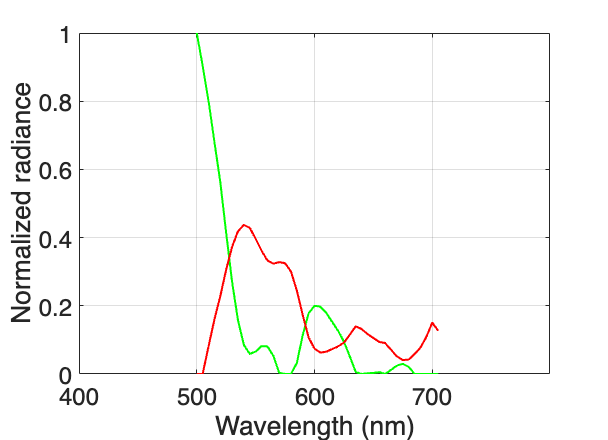

[~,cols] = size(allData);
for k = 1:4
    [Basis,H] = nnmf(allData,k);
    total_variance = sum(var(allData));
    approximation = Basis * H;
    explained_variance = sum(var(approximation));
    percent_variance = (explained_variance / total_variance) * 100;
    fprintf('k is %i',k);
    fprintf(' percent var acc for %.2f%%\n',percent_variance);
    figure;
    for jj = 1:cols
        plot(approximation(:,jj),allData(:,jj),'ko','LineWidth',2); hold on;
    end

    title(['Lip  Nfactors =' num2str(k), '    var acc for ' num2str(percent_variance,4)]);
    fontsize(gca,16,"pixels");
    xlabel('wavelength (nm');
    ylabel('Radiance (energy)');
end

Result: seems like at least two basis functions are required ... but this does not take into account the effect of absorption of collagen fluorescence by blood, and FAD.  

Question: Can we explain these results by two functions

- collagen * blood transmission

- FAD

**To answer this question, combine data across different lights (405, 415, 450)**


Basis = ieScale(Basis,1);
ieNewGraphWin;
plot(wave,Basis(:,1),'g','LineWidth',2); hold on;
plot(wave,Basis(:,2),'r','LineWidth',2); hold on;
plot(wave,Basis(:,3),'b','LineWidth',2); hold on;
grid on;
set(gca,'ylim',[0 1]);
set(gca,'xlim',[400 800]);
set(gca,'fontsize',24);
set(gca,'xtick',400:100:700);
xlabel('Wavelength (nm)');
ylabel('Normalized radiance');
